clearvars
%define the grid
Nx = 600;%600
Ny = 450;%450
dx = 2e-4;%2e-4
dy = 2e-4;%2e-4
Kgrid = kWaveGrid(Nx,dx,Ny,dy);
c = 1500;
%Kgrid.setTime

%Use point per wavelength ppl to reduce dx until stable
%dx = 2e-4 ppl = 37500
ppw = 40000;
wavelength = 1.5/120*Nx;
dx_new = wavelength/ppw

dx_new = 1.8750e-04

w = 1500/1e6%1.5mm

w = 0.0015

p = wavelength/dx

p = 37500


%define the medium prperty
medium.sound_speed = 1500;
medium.alpha_coeff = 0.75;
medium.alpha_power = 1.5;

% create the time array
Kgrid.makeTime(medium.sound_speed,0.3,6e-5);%128SQRT2/1500
t_array_new = Kgrid.t_array(1:126)

t_array_new = 1.0e-05 *

         0    0.0040    0.0080    0.0120    0.0160    0.0200    0.0240    0.0280    0.0320    0.0360    0.0400    0.0440    0.0480    0.0520    0.0560    0.0600    0.0640    0.0680    0.0720    0.0760    0.0800    0.0840    0.0880    0.0920    0.0960    0.1000    0.1040    0.1080    0.1120    0.1160    0.1200    0.1240    0.1280    0.1320    0.1360    0.1400    0.1440    0.1480    0.1520    0.1560    0.1600    0.1640    0.1680    0.1720    0.1760    0.1800    0.1840    0.1880    0.1920    0.1960



% define a single source point
source.p_mask = zeros(Nx, Ny);
source_x = 60/120*Nx;
source.p_mask(source_x, Ny/2) = 1;

% define a time varying sinusoidal source
source_freq = 1e6;   % [Hz]
source_mag = 3;         % [Pa]
source.p = source_mag * sin(2 * pi * source_freq * t_array_new);

% filter the source to remove high frequencies not supported by the grid
source.p = filterTimeSeries(Kgrid, medium, source.p);

Filtering input signal...
  maximum frequency supported by kgrid: 3.75MHz (2 PPW)
  filter cutoff frequency: 2.5MHz (3 PPW)
  computation complete.



%define the sensor in a line
x_offset = 20/120*Nx % [grid points]

x_offset = 100

width = 50/90*Ny% [grid points]

width = 250

sensor.mask = zeros(Nx, Ny);
sensor.mask(x_offset, Ny/2 - width/2 + 1:7.8125:Ny/2 + width/2) = 1;

Running k-Wave simulation...
  start time: 06-Sep-2023 20:49:28
  reference sound speed: 1500m/s
  dt: 40ns, t_end: 60us, time steps: 1501
  input grid size: 600 by 450 grid points (120 by 90mm)
  maximum supported frequency: 3.75MHz
  precomputation completed in 0.15633s
  starting time loop...
  estimated simulation time 52.6251s...


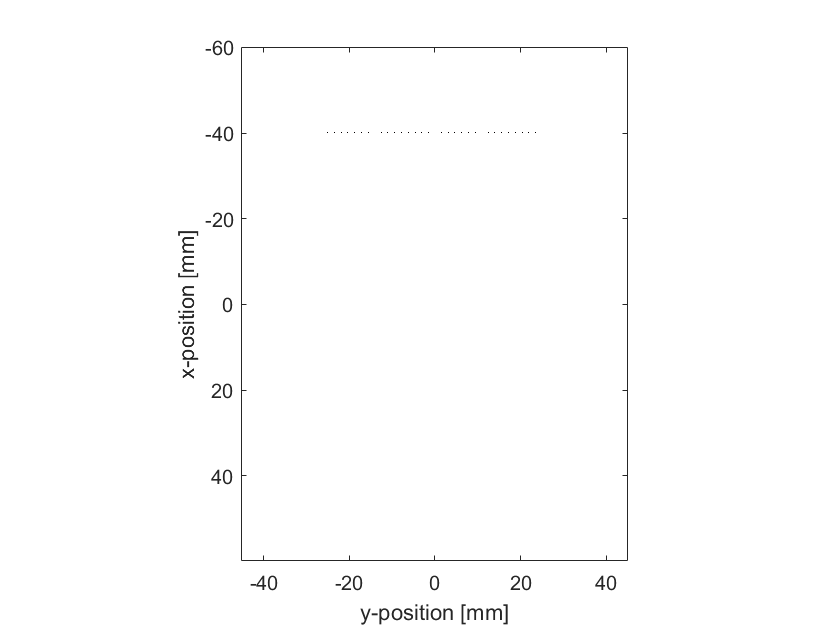

  simulation completed in 1min 0.35022s
  total computation time 1min 0.546s




% run the simulation
sensor_data = kspaceFirstOrder2D(Kgrid, medium, source, sensor);

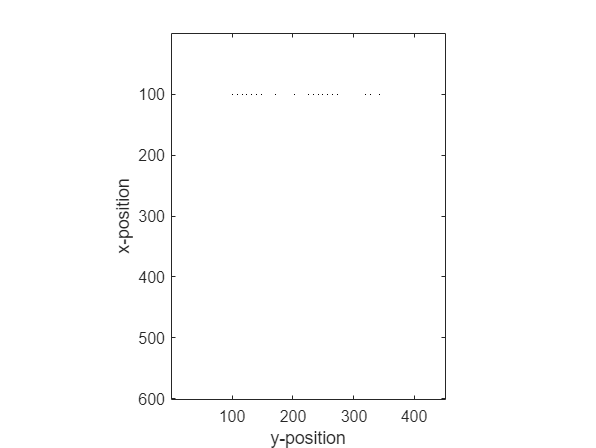




% VISUALISATION
% =========================================================================

% plot the initial pressure and sensor distribution
%positive max around 0.043-0.0449
figure;
%imagesc(Kgrid.y_vec * 1e3, Kgrid.x_vec * 1e3, source.p0 + cart2grid(Kgrid, sensor.mask), [-1, 1]);
imagesc(source.p_mask + sensor.mask, [-1, 1]);
%imagesc(source.p0 + sensor.mask, [-1, 1]);
colormap(getColorMap);
ylabel('x-position');
xlabel('y-position');
axis image;

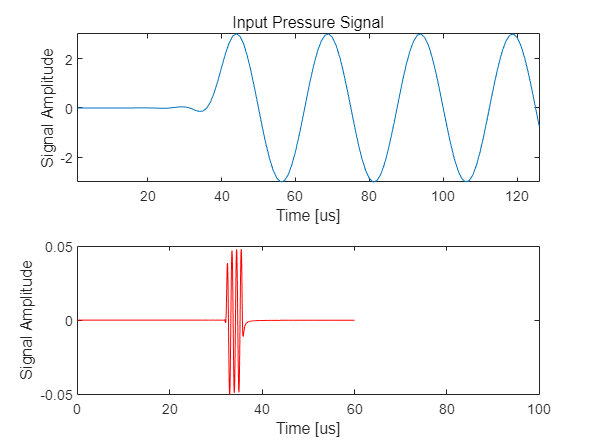

% plot the simulated sensor data
figure;
[t_sc, scale, prefix] = scaleSI(max(t_array_new));

subplot(2, 1, 1);
plot(source.p)
%plot(t_array_new * scale, source.p, 'k-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis ([-inf,inf,-inf,inf]);
title('Input Pressure Signal');

subplot(2, 1, 2);
plot(Kgrid.t_array * scale, sensor_data(32,:), 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis ([0,100,-0.05,0.05]);

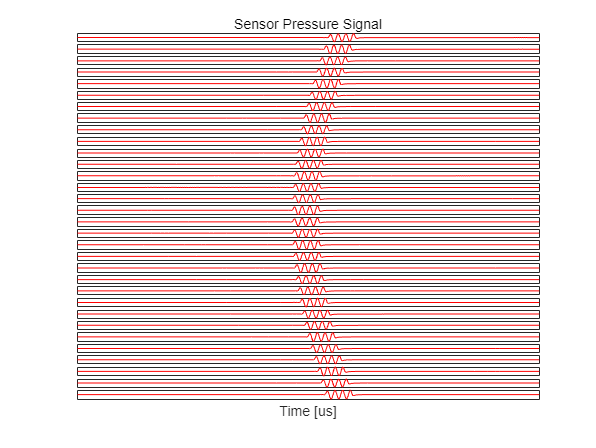

%axis tight;
%axis([0,10.5,-inf,inf]);



%plot all the 32 original sensor signal 
figure
for i = 1:32
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, sensor_data(i,:), 'r-');

    %axis([0,10.5,-inf,inf]);
    set(gca,'XTick',[],'YTick',[]);
    if i == 1
            %xlabel(['Time [' prefix 's]']);
            ylabel('Signal Amplitude');
            title('Sensor Pressure Signal');
    end
    if i == 32 
        xlabel(['Time [' prefix 's]']);
        %ylabel('Signal Amplitude');
        %title('Sensor Pressure Signal');
    end

end

## dt=40ns tend=100.04us timestep = 2502 totalt=1e-4

% Kgrid.t_array
% t_array_limit = 1/source_freq*5
% t_array_new = Kgrid.t_array(1:32)
% 1/2E-4
% 128*1.414/1500

tic

%obtian all the sensor position
sensorpoistion = zeros(1,32);
j=1

j = 1

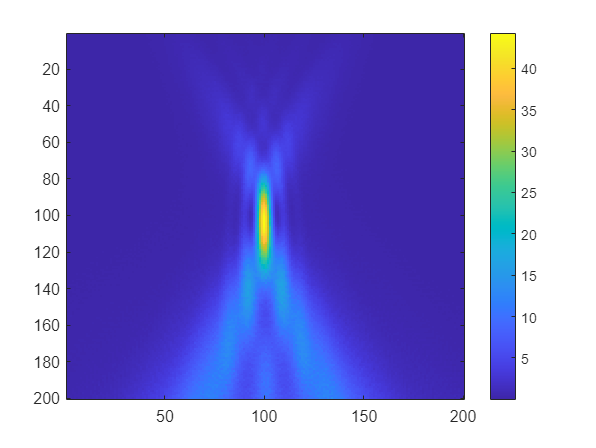

for i = 1:450
    if sensor.mask(100,i)==1
        
        sensorpoistion(j) = i;
        j = j+1;
    end
end
%sensorpoistion();

%distance from sensor to source mm
distance_map = zeros(1,32);
%sourceposition =[70/120*Nx, Ny/2]%x=350,y=225
distance = zeros(1,32);
for i = 1:32
    distance(i) = sqrt((sensorpoistion(i)-225)^2+(350-100)^2);
end


%all the source position

%Create a 20mm times 20mm grid, which is 200 times 200
%x from 
map_length = zeros(1,200);
map_width = zeros(1,200);
%x_offset, Ny/2 - width/2 + 1:7.8125:Ny/2 + width/2

for i = 1:200
    map_length(i)=source_x-Nx/6+i;
    map_width(i)=225-20/90*Ny+i;
end
%map_length
%map_width
%x = 350-map_width:350+map_width
%y = 225-map_width:225+map_width


%the intensity map position
%map_width = 40/120*Nx;
%map = zeros(map_width,map_width);

%store the map postion
step = zeros(1,32);
timespan = length(Kgrid.t_array);
sensor_data_test = zeros(32,timespan);
sensor_data_new = zeros(32,timespan);
coeff = 4/32*pi;
%times distance with the sensor data3m
%define the energy map
energymap = zeros(200,200);

%sensorpoistion;
for m = 1:200
     for n = 1:200
         A = zeros(32,timespan);
        for i = 1:32
            %calculate distance from each point
            distance_map(1,i)=sqrt((sensorpoistion(i)-map_width(m))^2+(map_length(n)-100)^2);
            timeshift = distance_map*dx/c;

            
            %apply the time delay to the sensor data
            step(i) = floor(timeshift(i)/4e-8);
            sensor_data_test(i,:) = sensor_data(i,:);
            sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));
            A(i,:) = distance_map(i)*sensor_data_new(i,:);
        end
        %sum 32 sensor data together
        sum_A = sum(A);
        intensity = coeff * sum_A;

        %integral'
        intensity_2 = intensity.^2;
        Q = trapz(intensity_2);
        coeff2 = 1/(4*pi*1500);
%         energymap(n,m)= intensity_2*intensity_2'/32/32*coeff2;
        energymap(n,m)= Q*coeff2;
     end
end

% figure
% imshow(energymap,[])
% 
% 
% intensity_2*intensity_2'/32/32
% Q
% 
% figure
% 
% %imshow(energymap/256)
% 
% imshow(uint8(energymap))
% 
% rea = im2uint8(mat2gray(energymap));
% figure
% imshow(rea)

% step
% timeshift
% distance_map
% for m = 1:200
%     for n = 1:200
%         i
%         for i = 1:32
%             %calculate distance from each point
%             distance_map(1,i)=sqrt((sensorpoistion(i)-map_width(n))^2+(map_length(m)-100)^2);
%             timeshift = distance_map*dx/c;
% 
%             
%             %apply the time delay to the sensor data
% %             step(i) = floor(tj(i)/4e-8);
% %             sensor_data_test(i,:) = sensor_data(i,:);
% %             sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));

%         end
%     end
% end


figure

%imshow(energymap/256)

%imshow(uint8(energymap))
imagesc(energymap);
colorbar;  % colorbar 的作用是生成一个代表颜色值的条状图例


toc

历时 16.419089 秒。


%source strength = 4pi/N*sum(distance*signal)

%normalize image
min_value = min(min(energymap))
max_value = max(max(energymap))
normalized_array = (energymap - min_value) / (max_value - min_value);
imagesc(normalized_array);
colorbar;  % colorbar 的作用是生成一个代表颜色值的条状图例


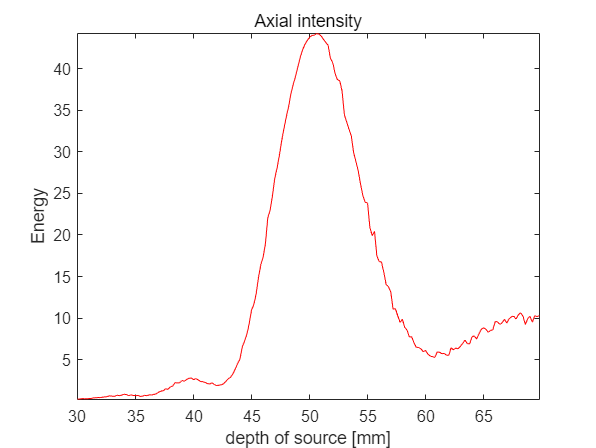


%axial resolution
index = 30:0.2:69.8;
axial = zeros(1,200);
for i = 1:200
    axial(i)= energymap(i,100);
end

% plot the value
figure;
[t_sc, scale, prefix] = scaleSI(max(map_length));


plot(index,axial,'r-')
%plot(t_array_new * scale, source.p, 'k-');
xlabel(['depth of source [mm]']);
ylabel('Energy');
axis ([-inf,inf,-inf,inf]);
title('Axial intensity');


% left value
leftEdge = find(axial >= 0.5*max(axial), 1, 'first')

leftEdge = 84


% right value
rightEdge = find(axial >= 0.5*max(axial), 1, 'last')

rightEdge = 126


% width
fwhmWidth = (rightEdge - leftEdge);

% 打印 FWHM 宽度
fprintf('FWHM width: %.2f mm', fwhmWidth);

FWHM width: 42.00 mm

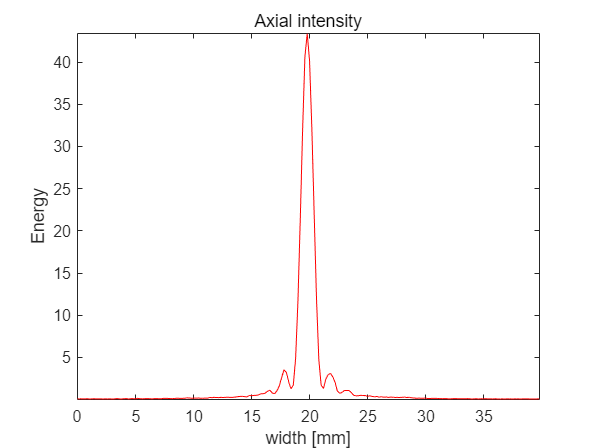



%lateral resolution
index = 0:0.2:39.8;
lateral = zeros(1,200);
for i = 1:200
    lateral(i)= energymap(100,i);
end

% plot the value
figure;
[t_sc, scale, prefix] = scaleSI(max(map_width));


plot(index,lateral,'r-')
%plot(t_array_new * scale, source.p, 'k-');
xlabel(['width [mm]']);
ylabel('Energy');
axis ([-inf,inf,-inf,inf]);
title('Axial intensity');


% left value
leftEdge = find(lateral >= 0.5*max(lateral), 1, 'first')

leftEdge = 98


% right value
rightEdge = find(lateral >= 0.5*max(lateral), 1, 'last')

rightEdge = 103


% width
fwhmLength = (rightEdge - leftEdge)*dx;

% 打印 FWHM 宽度
fprintf('FWHM width: %.4f m', fwhmLength);

FWHM width: 0.0010 m

%normalize image
min_value = min(min(energymap))

min_value = 0.0249

max_value = max(max(energymap))

max_value = 44.1854

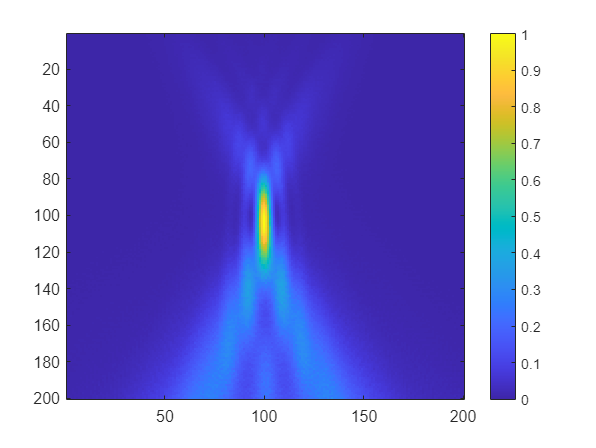

normalized_array = (energymap - min_value) / (max_value - min_value);
imagesc(normalized_array);
colorbar;  % colorbar 的作用是生成一个代表颜色值的条状图例


coeff = 4/32*pi

coeff = 0.3927

%distance_total = sum(distance, 'all')


%Shift test
%1st calculate how much time step to move
% step = tj(1)/4e-8%how many step to move
% step = floor(step)
% sensor_data_test = sensor_data(1,:)
% sensor_data_new = circshift(sensor_data_test, -step)

%shift test2
% function [AfterArray] = ArrayDisplacement(BeforeArray,direction,len,type)
% ArrayEnd = length(BeforeArray);
% eforeArrayL = BeforeArray(1:len);
% BeforeArrayR = BeforeArray(len+1:ArrayEnd);
% BeforeArrayL = fliplr(BeforeArrayL);
% BeforeArrayR = fliplr(BeforeArrayR);
% BeforeArray = [BeforeArrayL BeforeArrayR];
% AfterArray = fliplr(BeforeArray);

%apply the time delay to the sensor data
step = zeros(1,32)

step =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


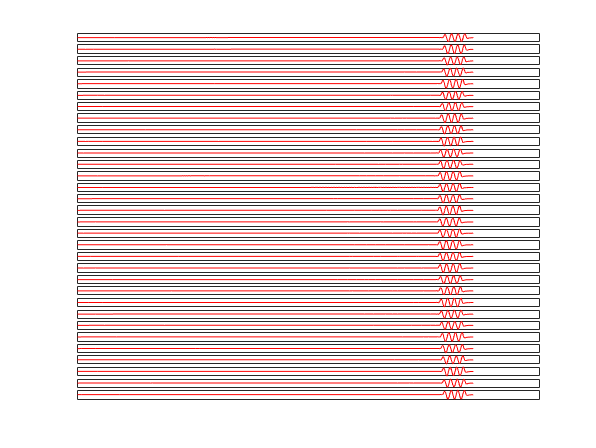

timespan = length(Kgrid.t_array);
sensor_data_test = zeros(32,timespan);
sensor_data_new = zeros(32,timespan);
tj = distance*dx/c;
for i = 1:32
    step(i) = floor(tj(i)/4e-8);
    sensor_data_test(i,:) = sensor_data(i,:);
    sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));
    %plot the shifted data 
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, sensor_data_new(i,:), 'r-');
    set(gca,'XTick',[],'YTick',[]);
    %axis([0,10.5,-inf,inf]);
end

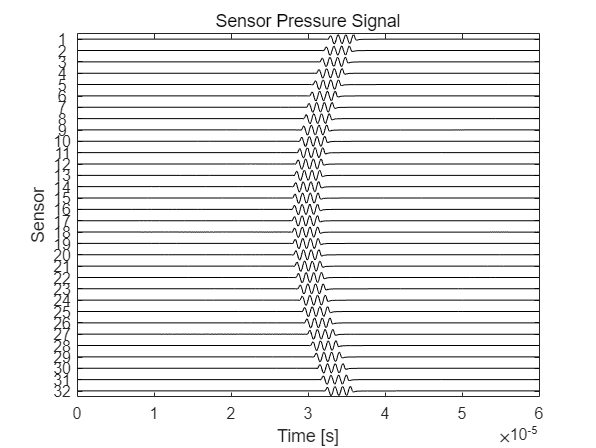




figure

stackedPlot(Kgrid.t_array,sensor_data)
ylabel('Sensor');
xlabel(['Time [' prefix 's]']);
title('Sensor Pressure Signal');

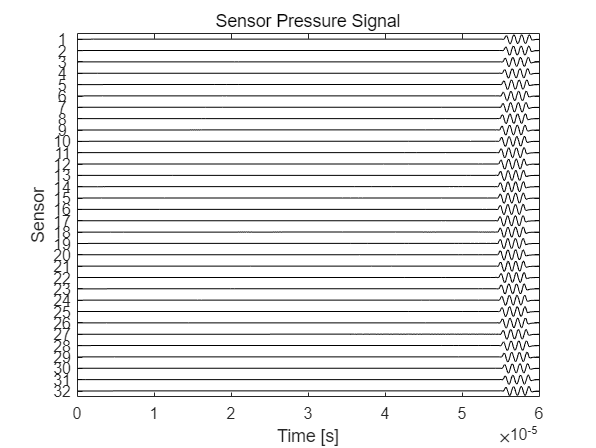


figure
stackedPlot(Kgrid.t_array,sensor_data_new)
ylabel('Sensor');
xlabel(['Time [' prefix 's]']);
title('Sensor Pressure Signal');



%calculate intensity
figure
A = zeros(32,1251)

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

A(1,:) = distance(1)*sensor_data_new(1,:);

无法执行赋值，因为左侧的索引与右侧的大小不兼容。

for i = 1:32
    A(i,:) = distance(i)*sensor_data_new(i,:);
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, A(i,:), 'r-');
    set(gca,'XTick',[],'YTick',[]);
end
figure
sum_A = sum(A)

%plot(Kgrid.t_array * scale, sum_A, 'r-');
intensity = coeff * sum_A
plot(Kgrid.t_array * scale, intensity, 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Source strength');


%integral'
intensity_2 = intensity.^2;
Q = trapz(intensity_2)
coeff2 = 1/(4*pi*1500)
%fun = @(x) exp(-x.^2).*log(x).^2;
fun = @(x) (coeff2*sum(A)).^2
%fun_2 = fun.^2
q = integral(fun,0,5e-05,'ArrayValued',true)
figure
plot(Kgrid.t_array * scale, q, 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Energy');



%original received signal
step(1)
%sensor_data_new(1,:) = circshift(sensor_data_test(1,:), -step);
figure
subplot(2,1,1);
plot(Kgrid.t_array * scale, sensor_data_test(1,:), 'r-');
set(gca,'XTick',[],'YTick',[]);
xlabel(['Time [' prefix 's]']);
%shifted signal
subplot(2,1,2);
plot(Kgrid.t_array * scale, sensor_data_new(1,:), 'r-');
xlabel(['Time [' prefix 's]']);

% sensor_data_new = distance * sensor_data
% figure
% subplot(2,1,1);
% plot(Kgrid.t_array * scale, sensor_data_new, 'r-');
% subplot(2,1,2);
% plot(Kgrid.t_array * scale, sensor_data(31,:), 'r-');


help kWaveGrid